# Tutorial: Virtual populations

To assess the impact of variability or uncertainty on model predictions, virtual populations are often studied in PBPK modelling exercises. In this tutorial, you will learn how to implement such as study in the MATLAB PBPK toolbox.

As an example, we will assess the impact of human physiology on predicted plasma PK profiles. To this end, we will simulate a PBPK model for 20 different realistic physiologies and aggregate the results as percentile plots.

Let us first allocate an `Observable` and a size 20 `Individual` array:

obs = PBPKobservables();
N = 20;
indv = Individual(N,'Virtual');

For simplicity, we consider the same dosing and sampling scheme for everybody. We will define this for individual 1 and copy it later to the other individuals.

A one-hour iv infusion of 60 milligram Amitriptyline, 

indv(1).dosing = Infusion('Amitriptyline', 0*u.h, 60*u.mg, 1*u.h, 'iv');

the associated drug data,

indv(1).drugdata   = loaddrugdata('Amitriptyline','species','human');

and a one-day sampling schedule. 

indv(1).sampling   = Sampling((0:0.5:24)*u.h, obs);

Note that we specified the precise sampling times, and not start and end of the sampling interval. This is important for such studies since otherwise, the simulation output will not be available at the same timepoints because different internal ODE solver timesteps will be used for different physiologies. This makes the final aggregation step more complicated, which we want to avoid.

We choose the 12-compartment well-stirred model with the Rodgers&Rowland method.

indv(1).model  = sMD_PBPK_12CMT_wellstirred;
indv(1).model.options.tissuePartitioning = @rodgersrowland;

Next, we need to create a distribution of detailed physiologies as seen in real populations. This is done in two steps. First, we create a distribution of basic covariates according to the so-called "de la Grandmaison method". This method is implemented in function `humancovdistrib()`:

humans = humancovdistrib(N, 'male');

This creates a distribution of body weight and body height as expected for a male Caucasian population, including the correct correlation between body weight and body height.

We can look at some of the different created `Physiology` objects:

humans(1)

ans = 	Physiology object (unnamed) with parameters:

species: human
type: Caucasian
sex: male
age: 35 year
BH: 1.7225 m
BW: 65.679 kg

humans(2)

ans = 	Physiology object (unnamed) with parameters:

species: human
type: Caucasian
sex: male
age: 35 year
BH: 1.62 m
BW: 53.4278 kg

and so on. The next step is to use a physiological scaling method to obtain a detailed physiology for each of these humans, which is required for the PBPK model we want to simulate. 

To this end, a reference physiology for scaling is defined, and for each object in the `Individual` array, we do the following. First, the common information on dosing, sampling, and so on is taken from the first individual. Then, the physiology is obtained via a physiological scaling method from the reference physiology to the human with simulated basic covariates. 

ref = Physiology('human35m');

for i=1:N
    indv(i) = clone(indv(1));
    indv(i).physiology = scaling_LBW(ref, humans(i));
end

We have now specified everything for simulation (takes ~10 seconds).

initialize(indv)
simulate(indv)

To represent the simulation results from a virtual population, we use a percentile plot, rather than the standard plasma concentration plots with one line per individual:

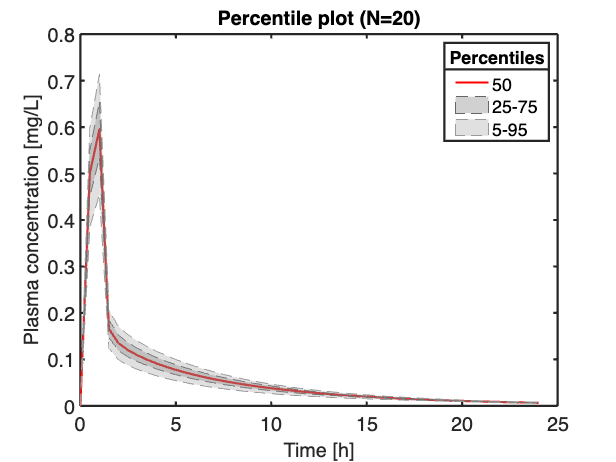

plot(indv, 'percentilesPlasmaConc','yunit','mg/L')

One thing to note is that a virtual population can also differ in other aspects than the physiology. For example, one or several drug-related parameter might be uncertain, and we could use this simulation to see the impact of this uncertainty. Or some model parameters themselves could be uncertain because the prediction method is not completely accurate, like for partition coefficients. Each of these scenarios will require to set up a dedicated virtual population to study this effect.